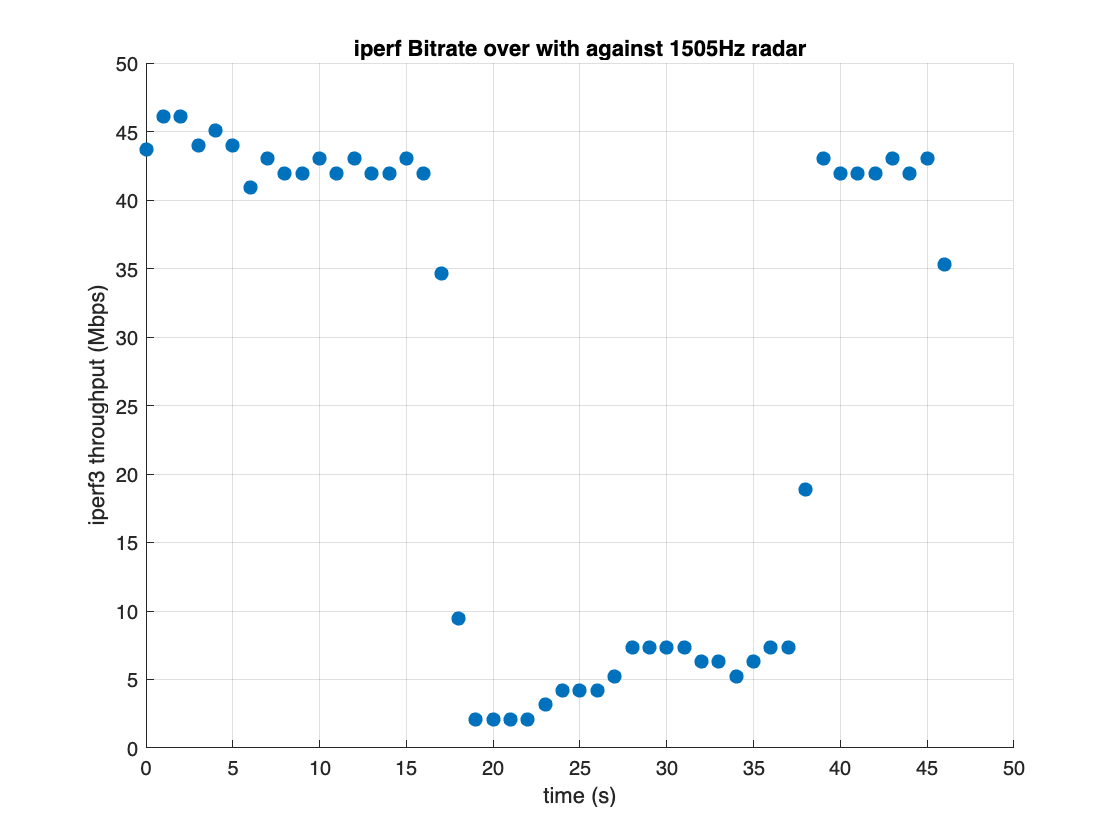

clear
close all
saveFolder = 'radarTestData_20250426_bler10' ;
% saveFile = '1_AvgData.csv'
saveFile = '1505_1Hz.iperf.csv';
parts = split(saveFile, '_'); % Split the string at the underscore
prf = parts{1}; % Extract the first part
data = readtable(strcat(saveFolder,'/',saveFile));  % Read the CSV file into a table
data = rmmissing(data);
figure;
gcf;
hold on;
grid on;
% titletxt=strcat('iperf Bitrate over time against',' ',prf, 'Hz radar';
txt = ['iperf Bitrate over with against ',prf, 'Hz radar'];
title(txt);
xlabel('time (s)');
ylabel('iperf3 throughput (Mbps)');
scatter(data.Time,data.Bitrate,50,'filled')
save_name = strcat('iperfPlots','/',saveFolder, '_', prf);
saveas(gcf, strcat(save_name, '.png'));  % Save as PNG

clear
close all
saveFolder = 'radarTestData_20250426_bler10' ;
% saveFile = '1_AvgData.csv'
saveFile = 'iperfLowPoints';
parts = split(saveFile, '_'); % Split the string at the underscore
prf = parts{1}; % Extract the first part
data = readtable(strcat(saveFolder,'/',saveFile)) % Read the CSV file into a table

data = 463×3 table
    PRF           Filename           AverageLowPoint_Mbps_
    ___    ______________________    _____________________

    NaN    {'.iperf.csv'        }            42.38        
      5    {'0005_8Hz.iperf.csv'}            41.87        
      5    {'0005_1Hz.iperf.csv'}            41.28        
      5    {'0005_4Hz.iperf.csv'}            41.84        
      5    {'0005_7Hz.iperf.csv'}            41.59        
      5    {'0005_2Hz.iperf.csv'}             41.8        
      5    {'0005_5Hz.iperf.csv'}            41.56        
      5    {'0005_3Hz.iperf.csv'}             41.6        
      5    {'0005_6Hz.iperf.csv'}             41.7        
     30    {'0030_1Hz.iperf.csv'}            39.17        
     30    {'0030_2Hz.iperf.csv'}            40.05        
     55    {'0055_2Hz.iperf.csv'}            38.57        
     55    {'0055_1Hz.iperf.csv'}            39.17  

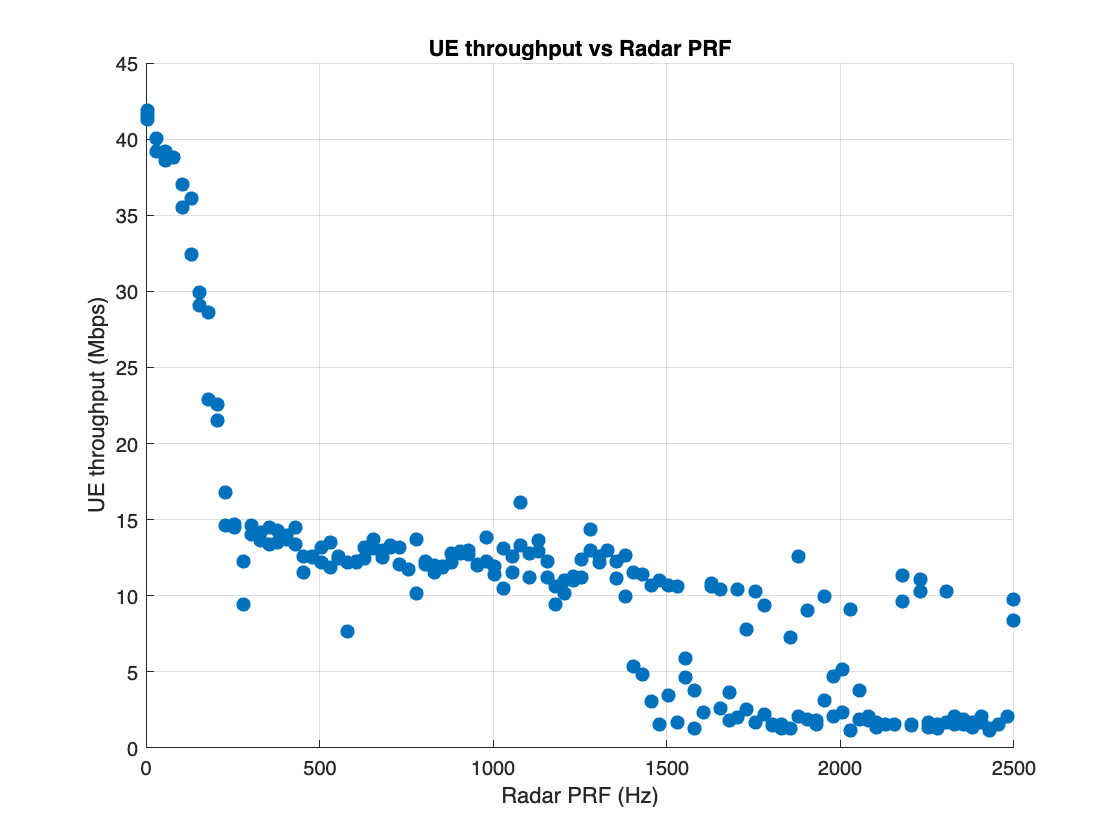

figure;
gcf;
hold on;
grid on;
% titletxt=strcat('iperf Bitrate over time against',' ',prf, 'Hz radar';
txt = ['UE throughput vs Radar PRF'];
title(txt);
xlabel('Radar PRF (Hz)');
ylabel('UE throughput (Mbps)');
xlim([0 2500])
scatter(data.PRF,data.AverageLowPoint_Mbps_,50,'filled')
save_name = ['iperfPlots','/',saveFile];
saveas(gcf, strcat(save_name, '.png'));  % Save as PNG